# Create a List from a MATLAB® Array

You can create a list from a MATLAB® array where each element represents a list item. 

To create an unordered list, append the array directly to a document or document part object. The `append` method creates an `mlreportgen.dom.UnorderedList` object from the array.

To create an ordered list, provide the array as the input argument to the `mlreportgen.dom.OrderedList` constructor. You can also create an unordered list by providing the array to the `mlreportgen.dom.UnorderedList` constructor`.`

The MATLAB array can be a 1-by-n numeric array, an array of character vectors, a categorical array, or a cell array. Use a cell array to specify elements having different types and to specify an element as a  DOM object, such as an `mlreportgen.dom.Text` object. If you use an n-by-1 array instead of an 1-by-n array, the DOM API generates a table, not a list.

This example represents list items as elements of a cell array and then appends the cell array to a document. 

import mlreportgen.dom.*;
d = Document('myListReport','html');

t = Text('third item');
append(d,{'first item',6,t,'fourth item'});

close(d);
rptview(d);

Here is the generated unordered list:

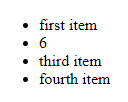

To generate an ordered list, create an `orderedList` object from the array and append the object to the document.

import mlreportgen.dom.*;
d = Document('myListReport','html');

t = Text('third item');
append(d,OrderedList({'first item',6,t,'fourth item'}));

close(d);
rptview(d);

Here is the generated ordered list:

*Copyright 2019 The MathWorks, Inc.*